# 第2章 离散时间信号和系统分析基础

## 2.3 离散时间信号的表示及运算规则

### 2.3.1 序列的表示法

#### `Ch2_3_1`

#### 示例1：用图示法来表示离散时间信号

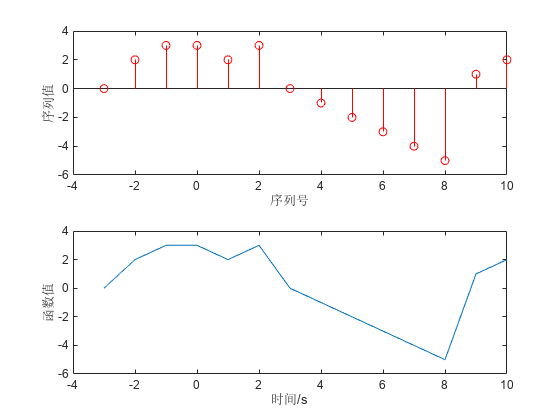

%序列序号
N = [-3 -2 -1 0 1 2 3 4 5 6 7 8 9 10];  

%序列值
X = [0 2 3 3 2 3 0 -1 -2 -3 -4 -5 1 2]; 

subplot(2,1,1);
%绘制离散值图
stem(N,X);  
hold on;

%绘制横轴
%用zeros(1,N)为产生1行N列元素值为零的数组，来绘制横轴，红色
%plot(N,zeros(1,length(X)),'r');

%产生坐标轴，设在方框上
%set(gca,'box','on');  
%2014早期版本用set，现在用图形对象
ss = stem(N,X);
ss.Color = 'red';

xlabel('序列号');
ylabel('序列值');

dt = 1;      %时间间隔（采样周期）
t = N*dt;    %时间序列
subplot(2,1,2);
plot(t,X);  %绘制随时间的变化
hold on;
%绘出横轴
%plot(t,zeros(1,length(X)),'r');  
xlabel('时间/s');
ylabel('函数值');

#### 示例2：绘出原始信号和采样后的信号

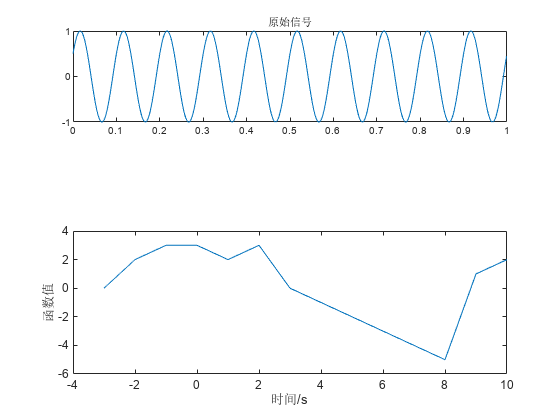

dt = 0.001;
n = 0:1000-1;
t = n*dt;
f = 10;                    %原始信号的频率为10Hz  x = sin(2*pi*ft)  
x = sin(2*pi*f*t + pi/6);  %在计算机上的原始信号
subplot(3,1,1);
plot(t,x);
% 绘出模拟原始信号,为与下图统一,采样y轴的范围[-1 1]用ylim给出
ylim([-1,1]);
title('原始信号');

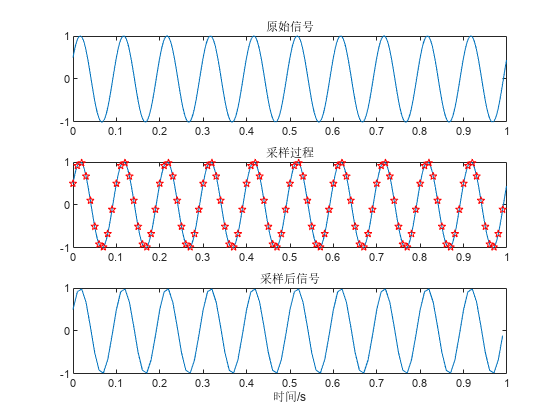


% 采样频率：100Hz
dt = 0.01; 
n = 0:100-1;
t1 = n*dt;

% 以100Hz的采样频率采样,为取一样的时间长度
% 序号长度为原始信号序号长度的1/10
x1 = sin(2*pi*f*t1 + pi/6);  %采样后的信号

% 绘出在模拟信号基础上的采样过程
subplot(3,1,2);
plot(t,x,t1,x1,'rp');
ylim([-1,1]);
title('采样过程');
%绘出采样后的信号

subplot(3,1,3);
plot(t1,x1);
ylim([-1,1]);
xlabel('时间/s');
title('采样后信号');